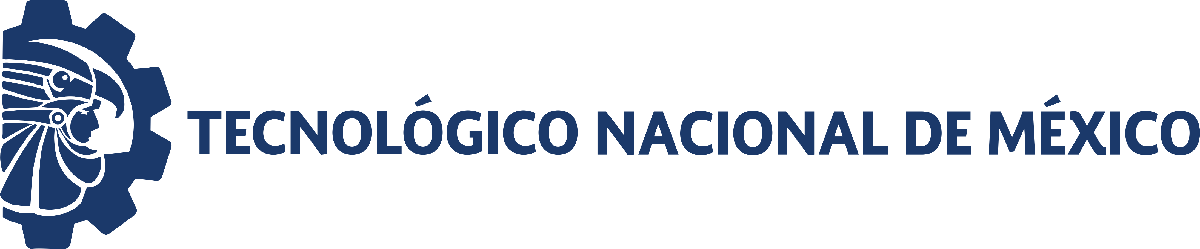                                 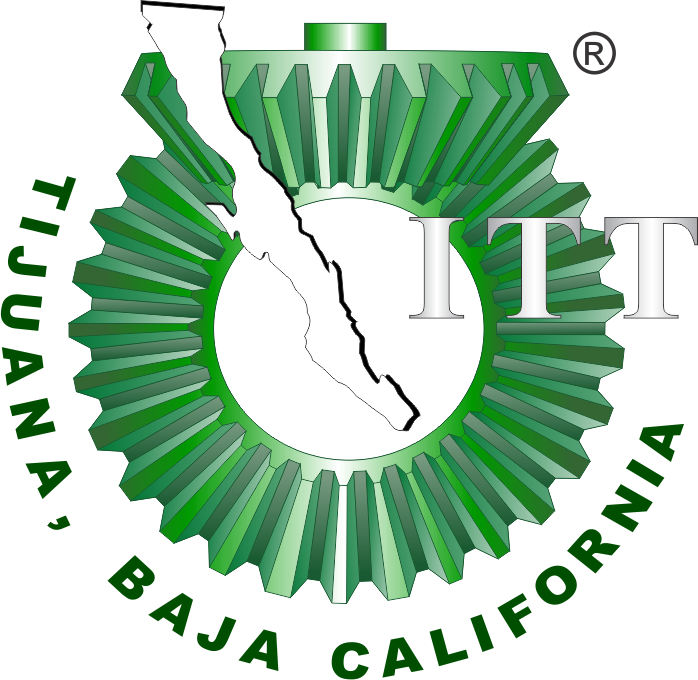

# Práctica 10: Regeneracion de globulos rojos

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

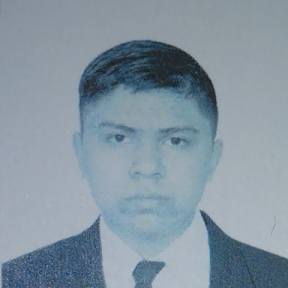

Nombre del alumno: **Garcia Sanchez Luis Fabian**

Número de control: **22212254**

Correo institucional: **L22212254@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; format short; warning('off','all')
tend = 180; %Tiempo de la simulacion en dias
dt = 1E-3; %Intervalo de integracion para el metodo de solucion por diferencias finitas
n = round(tend/dt); %Cantidad de iteraciones para el metodo numerico

%Condiciones iniciales base para cada paciente
x1_0 = 59; x2_0 = 44; x3_0 = 885;

%Parametros particulares para cada paciente
gamma = [0.769; 0.388; 0.510; 0.590; 0.262; 0.324; 0.356; 0.089; 0.243; 0.057];
beta = [1.650; 0.867; 1.617; 2.615; 1.518; 2.676; 0.891; 2.557; 0.925; 0.879];

seed = 22212254; %Semilla para asegurar reproducibilidad
rng(seed, 'twister')
%Intervalo de las condiciones iniciales
xmin = 0.99; xmax = 1.01;
interval = xmin + (xmax - xmin).*rand(numel(gamma),1);

%Condiciones iniciales para cada paciente
x1_0 = x1_0*interval; disp('x1(0) = '); disp(x1_0);...
x2_0 = x2_0*interval; disp('x2(0) = '); disp(x2_0);...
x3_0 = x3_0*interval; disp('x3(0) = '); disp(x3_0);

x1(0) = 
   58.5487
   58.8003
   59.2134
   58.4320
   59.1558
   59.0415
   59.1196
   58.5739
   58.5096
   58.7823



x2(0) = 
   43.6634
   43.8511
   44.1592
   43.5764
   44.1162
   44.0309
   44.0892
   43.6822
   43.6343
   43.8376



x3(0) = 
  878.2301
  882.0049
  888.2016
  876.4794
  887.3363
  885.6218
  886.7946
  878.6084
  877.6436
  881.7344



## Caso: Sin transfusion sanguinea [u(t) = 0]

u = zeros(n+1,1); %No hay transfusion
fig = 1;
for i = 1:10
    [t,x1,x2,x3] = system(x1_0(i),x2_0(i),x3_0(i),beta(i),gamma(i),u,dt,tend);
    plotdata(t,x1,x2,x3,fig)
end

## Caso: Con transfusion sanguinea

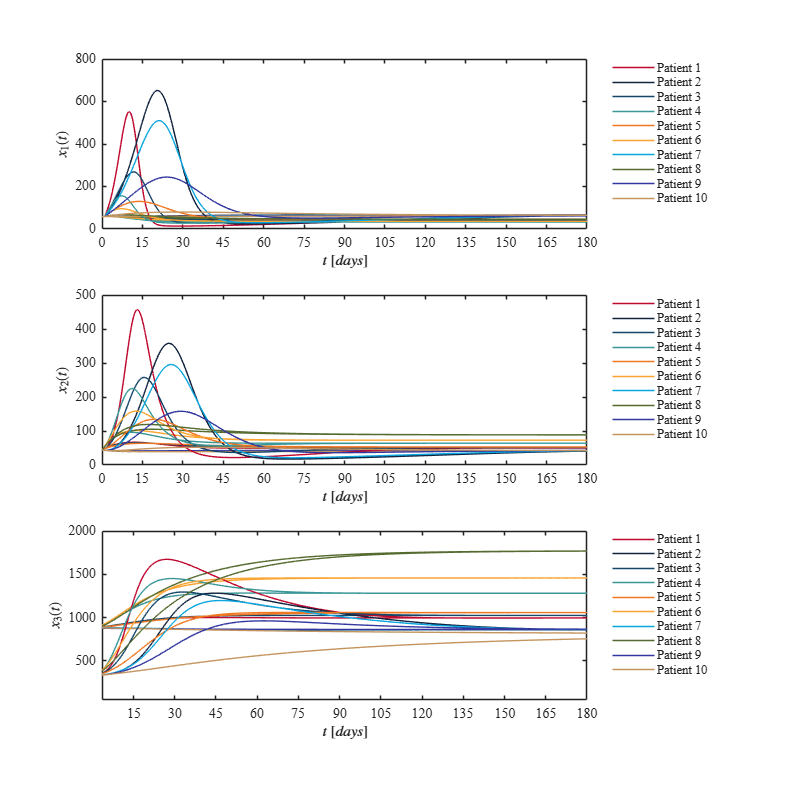

u = zeros(n+1,1);
u(1:1000) = 1;
fig = 2;
for i = 1:10
    [t,x1,x2,x3] = system(x1_0(i),x2_0(i),x3_0(i),beta(i),gamma(i),u,dt,tend);
    plotdata(t,x1,x2,x3,fig)
end

## Funcion: Modelo matematico


$${\dot{x} }_1 =\beta \left(X_0 -k_1 x_1 \right)+\frac{\gamma \left(B_{\textrm{ase}} -x_3 \right)\left(1-u\left(t\right)\right)x_1 }{B_{\textrm{ase}} }$$



$${\dot{x} }_2 =\beta \left(k_1 x_1 -k_2 x_2 \right)$$



$${\dot{x} }_3 =\beta \left(k_2 x_2 -\alpha x_3 \right)-u\left(t\right)x_3$$


function [t,x1,x2,x3] = system(x1_0,x2_0,x3_0,beta,gamma,u,dt,tend)
    %Parametros fijos del sistema
    Base = 885.42; X0 = 7.3785; k1 = 0.125; k2 = 0.1667; alpha = 0.00833;
    t = (0:dt:tend)';
    n = round(tend/dt);
    x1 = zeros(n+1,1); x1(1) = x1_0;
    x2 = zeros(n+1,1); x2(1) = x2_0;
    x3 = zeros(n+1,1); x3(1) = x3_0;

    for i = 1:n %Metodo de Euler (diferencias finitas)
        x1(i+1) = x1(i) + (beta*(X0 - k1*x1(i)) + gamma*(Base - x3(i))*(1 - u(i))*x1(i)/Base)*dt;
        x2(i+1) = x2(i) + (beta*k1*x1(i) - k2*x2(i))*dt;
        x3(i+1) = x3(i) + (beta*(k2*x2(i) - alpha*x3(i)) - u(i)*x3(i))*dt;
    end
end

## Funcion: Soluciones en el tiempo

function plotdata(t,x1,x2,x3,fig)
    set(figure(fig),'color','w')
    set(gcf,'Units','Centimeters','Position',[1,1,20,20])
mycolors = [191, 9, 47;
    19, 36, 64;
    22, 71, 106;
    59, 151, 151;
    239, 119, 34;
    250, 165, 51;
    11, 166, 223;
    85, 107, 47;
    51, 56, 160;
    197, 149, 96]/255;
    subplot(3,1,1)
    hold on; grid off; box on; colororder(mycolors)
    plot(t,x1)
    xlabel('$t$ $[days]$','Interpreter','latex','FontSize',10)
    ylabel('$x_1(t)$','Interpreter','latex','FontSize',10)
    xlim([0 180]); xticks(0:15:180)
    L = legend('Patient 1','Patient 2','Patient 3','Patient 4','Patient 5',...
    'Patient 6','Patient 7','Patient 8','Patient 9','Patient 10');
    set(L,'FontSize',9,'Box','Off','Location','NorthEastOutside');
    set(gca,'FontName','Times New Roman','FontSize',10)

    subplot(3,1,2)
    hold on; grid off; box on; colororder(mycolors)
    plot(t,x2)
    xlabel('$t$ $[days]$','Interpreter','latex','FontSize',10)
    ylabel('$x_2(t)$','Interpreter','latex','FontSize',10)
    xlim([0 180]); xticks(0:15:180)
    L = legend('Patient 1','Patient 2','Patient 3','Patient 4','Patient 5',...
    'Patient 6','Patient 7','Patient 8','Patient 9','Patient 10');
    set(L,'FontSize',9,'Box','Off','Location','NorthEastOutside');
    set(gca,'FontName','Times New Roman','FontSize',10)

    subplot(3,1,3)
    hold on; grid off; box on; colororder(mycolors)
    plot(t,x3)
    xlabel('$t$ $[days]$','Interpreter','latex','FontSize',10)
    ylabel('$x_3(t)$','Interpreter','latex','FontSize',10)
    xlim([0 180]); xticks(0:15:180)
    L = legend('Patient 1','Patient 2','Patient 3','Patient 4','Patient 5',...
    'Patient 6','Patient 7','Patient 8','Patient 9','Patient 10');
    set(L,'FontSize',9,'Box','Off','Location','NorthEastOutside');
    set(gca,'FontName','Times New Roman','FontSize',10)

    if fig == 1
        exportgraphics(gcf,'Caso Sin transfusion.pdf','ContentType','Vector')
    elseif fig == 2
        exportgraphics(gcf,'Caso Con transfusion.pdf','ContentType','Vector')
    end
end